# Tarea 2: Conceptos de Estadística        

#  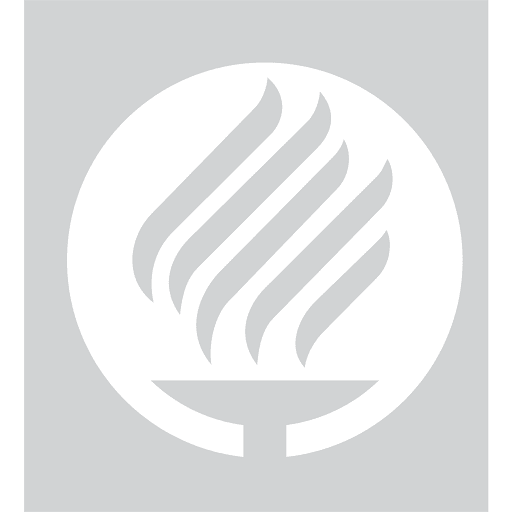

**Equipo:**

Mariana Alarcón Roel - A00828509

Ana Sofía Macías Amador - A0027483

Daniela Martínez Cepeda - A00824746

Daniela Oropeza Mosqueda -A00827945 

Ana Sofía Torres Sainz - A00827459

## Data set 

El data set que elegimos se trata de una comparación entre 31 países y sus salarios mínimos a lo largo de los años, desde el 2001 al 2018. Este data set se nos hizo interesante para analizar y comparar en gráficas, el salario mínimo del país que querramos, para así darnos una idea de la situación económica de un país y el estilo de vida. En este caso, elegimos México.

## Carga del archivo 

Para cargar el archivo de Excel (.csv) a Matlab, primero tuvimos que agregar el archivo a la carpeta de Matlab y luego usar la siguiente función. 

tabla= readtable(['salario.csv'])  %data base en forma de tabla 

tabla = 32×19 table
           Var1            Var2      Var3      Var4      Var5      Var6      Var7      Var8      Var9     Var10     Var11     Var12     Var13     Var14     Var15     Var16     Var17     Var18     Var19 
    __________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    

**Variables**

yrs=[tabla.Var2:tabla.Var19] %años del 2001 al 2018

yrs =         2001        2002        2003        2004        2005        2006        2007        2008        2009        2010        2011        2012        2013        2014        2015        2016        2017        2018


sal=[ table2array(tabla(18,2:19))] %el salario min de México cada años

sal = 	1.0e+03 *

    1.8867    1.9001    1.8993    1.8914    1.9006    1.9073    1.9059    1.8857    1.8736    1.8861    1.8988    1.9018    1.9101    1.9079    1.9466    2.0118    2.0790    2.1880


## Estadísticas descriptivas

**Media:** Es el promedio de una medida de tendencia central. Puede representar por si sola a un conjunto entero de valores.

m= mean(sal) %media 

m = 1.9323e+03

**Mediana: **Al ordenar todos los datos de menor a mayor, el valor que se encuentra justo en el medio es considerado la mediana. Si es par el conjunto de datos, se deben sumar los dos dígitos del medio y dividirse entre dos.

md = median(sal) %mediana 

md = 1.9012e+03

**Varianza:** Es una medida de la dispersión de una variable aleatoria (valores que se obtienen de manera aleatoria). Es ampliamente utilizada en el área de estadística expresando, a través de un número, la variabilidad de dicha dispersión.

v= var(sal)  %varianza

v = 6.6191e+03

**Desviación Estándar: **Es una medida que se utiliza para cuantificar la variación o la dispersión de un conjunto de datos numéricos

s= std(sal) %desviación estándar

s = 81.3581

## Gráficas

 La gráfica quedecidimos hacer una gráfica de barras 

y=yrs %años en el eje "y" 

y =         2001        2002        2003        2004        2005        2006        2007        2008        2009        2010        2011        2012        2013        2014        2015        2016        2017        2018


x=sal %salario min en el eje "x"

x = 	1.0e+03 *

    1.8867    1.9001    1.8993    1.8914    1.9006    1.9073    1.9059    1.8857    1.8736    1.8861    1.8988    1.9018    1.9101    1.9079    1.9466    2.0118    2.0790    2.1880


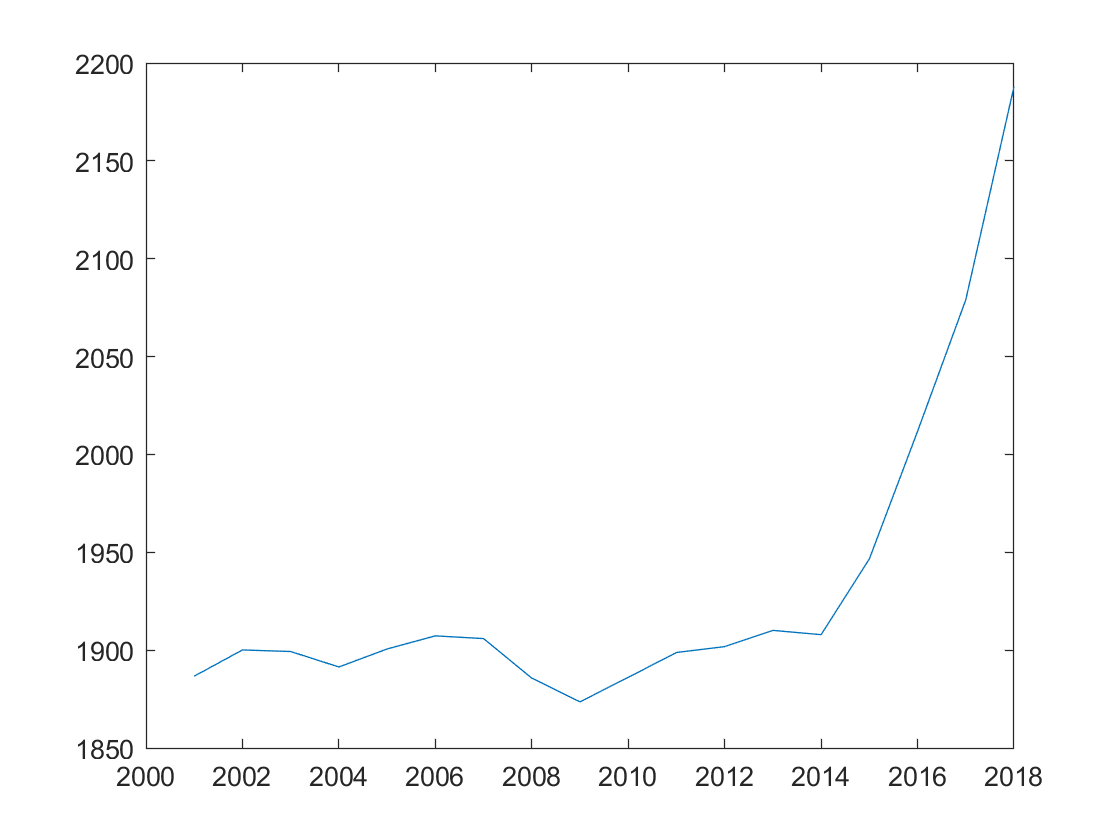

plot(y,x)

## Conclusiones 